clear all;close all;

basePath = 'C:\Users\sgrc-325\Desktop\git\pipes\data\p test\';

% fileNames = {'1225_13P.CSV'};  %squar
% fileNames = {'1226_0P.CSV'};  %stop
% fileNames = {'1226_6P.CSV'};  %stop
fileNames = {'1227_0P.CSV'};  %num fix 40 sqaur
% fileNames = {   %multiple data
%     '1224_2P.CSV', ...
%     '1224_3P.CSV', 
%     };
allData = [];

for i = 1:length(fileNames)
    filePath = fullfile(basePath, fileNames{i});
    tempData = readtable(filePath, 'Delimiter', ',', 'ReadVariableNames', false);
    allData = [allData; tempData]; % 將每個表格資料合併
end

moData=allData;

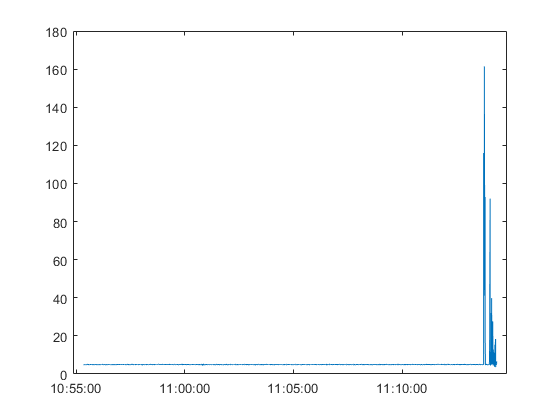

moData=allData(2000:end,:);
% moData=allData(2500:3200,:);
mo=[moData.Var1 moData.Var1 moData.Var1 moData.Var4 moData.Var5 moData.Var6 moData.Var7 moData.Var8 moData.Var9 moData.Var10 moData.Var11 moData.Var12 moData.Var13 moData.Var14 moData.Var15 moData.Var16 moData.Var17 moData.Var18 moData.Var19 moData.Var20];

[No,~]=size(mo);

t= moData.Var1;
time_rtc=moData.Var2;
time_gps=moData.Var3;
m = mo(:,4:6);
acc1 = mo(:,7:9);
gyr1=mo(:,10:12);
lat=mo(:,13);
lon=mo(:,14);
alt=mo(:,15);
sats=mo(:,16);
fix=mo(:,17);
hacc=mo(:,18);
vacc=mo(:,19);
tem=mo(:,20);

ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
gx1=gyr1(:,1);gy1=gyr1(:,2);gz1=gyr1(:,3);
mx=m(:,1);my=m(:,2);mz=m(:,3);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2);
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差

close all
tt = time_rtc;
% tt = time_gps;

figure(1)
plot(tt,GG)

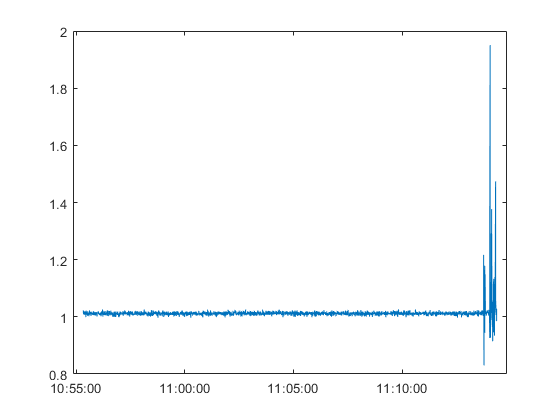

figure(2)
plot(tt,aG)

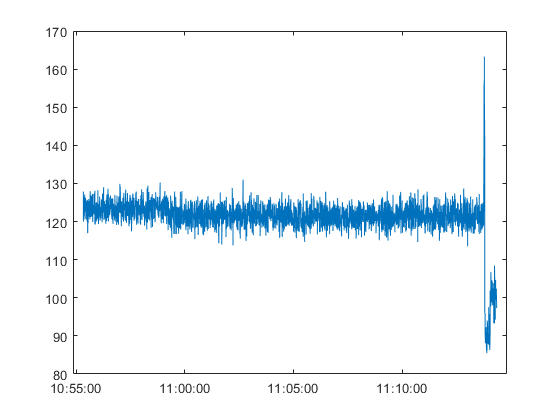

figure(3)
plot(tt,mm4)

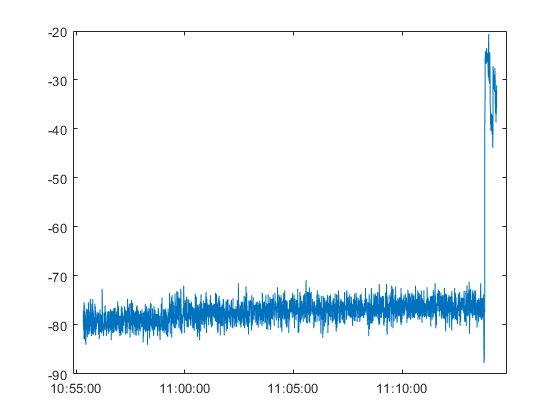


figure(4)
plot(tt,m(:,1))

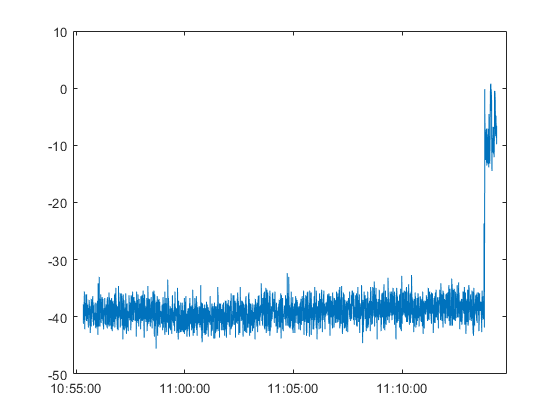

figure(5)
plot(tt,m(:,2))

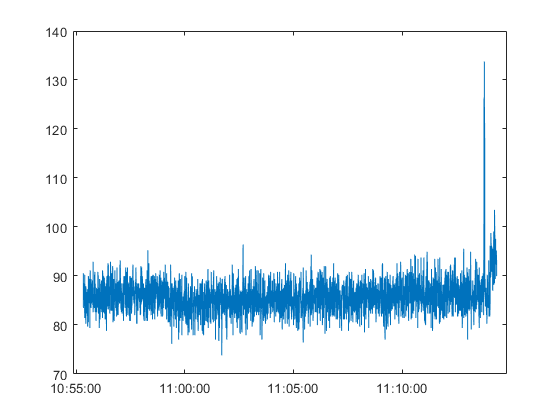

figure(6)
plot(tt,m(:,3))

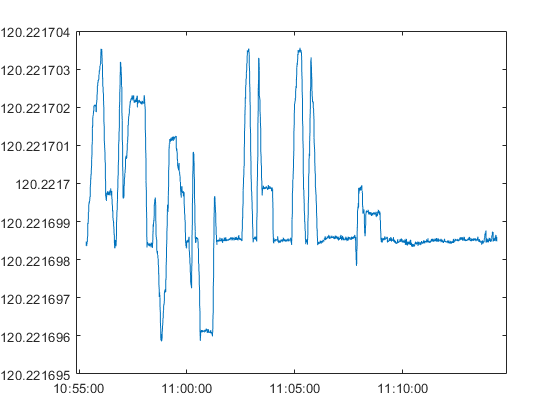


figure(7)
plot(tt,lon)

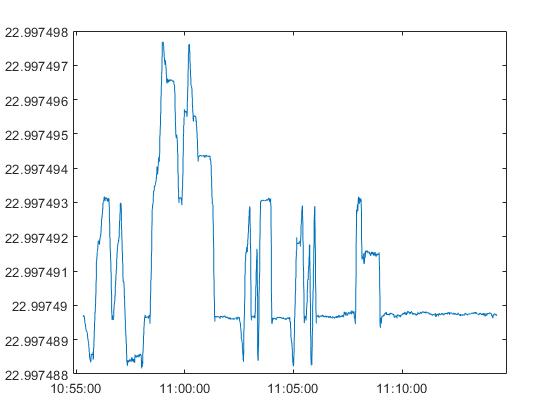

figure(8)
plot(tt,lat)

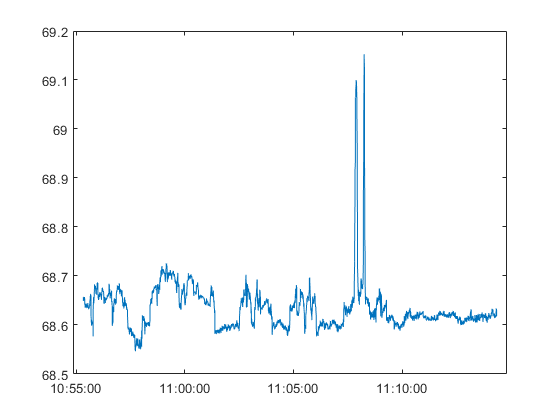

figure(9)
plot(tt,alt)

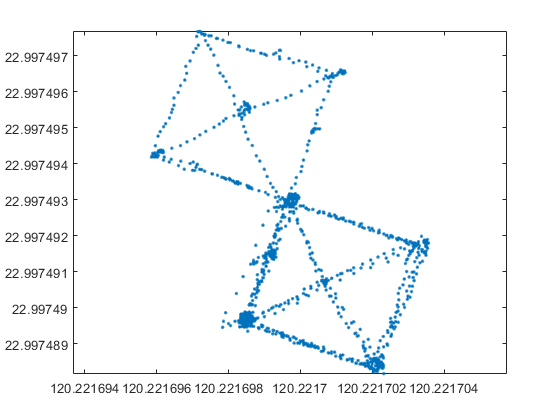

figure(10)
plot(lon,lat,'.')
axis equal;

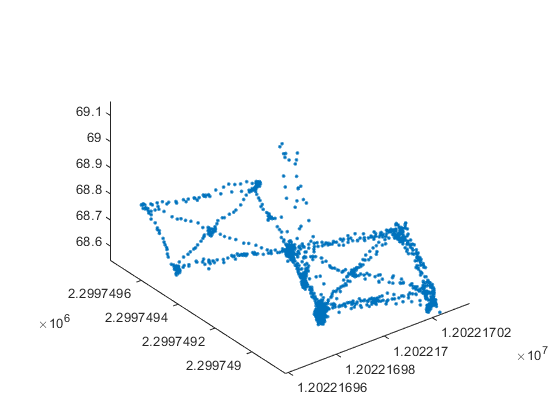

figure(11)
plot3(lon*100000,lat*100000,alt,'.')
axis equal;

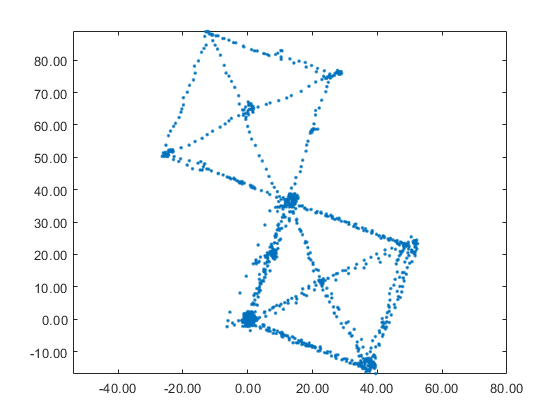

close all
% 設定投影參數，使用台灣西部二度分帶的 TWD97 座標系
latlon = [lat, lon]; % 經緯度資料組合為矩陣
twd97 = projcrs(3826); % TWD97 座標系

% 使用 projfwd 進行經緯度到座標的轉換
[x, y] = projfwd(twd97, latlon(:,1), latlon(:,2));

x=x*100; %m to cm
y=y*100;
altcm=alt*100;

x=x-x(1);
y=y-y(1);
altcm=altcm-altcm(1);
x1=[];y1=[];altcm1=[];

for i=1:No
    if(fix(i)>3)
        x1(end+1)=x(i);
        y1(end+1)=y(i);
        altcm1(end+1)=altcm(i);
    end
end

figure(1)
p=plot(x1,y1,'.');
axis equal;
pgca = gca; % 取得當前座標軸
agca.XAxis.Exponent = 0; % 禁止顯示科學記數法
agca.YAxis.Exponent = 0;
xtickformat('%.2f'); % 軸顯示到小數點後3位
ytickformat('%.2f');

p.DataTipTemplate.DataTipRows(1).Format = '%.5f'; % 軸DataTip顯示到小數點後8位
p.DataTipTemplate.DataTipRows(2).Format = '%.5f';

std(x1)

ans = 15.8409

std(y1)

ans = 23.5448

std(altcm1)

ans = 4.9705

t(end)

ans = 1.9493e+03

fprintf('%s to %s\n', datestr(time_rtc(1)), datestr(time_rtc(end)));

10:55 AM to 11:14 AM


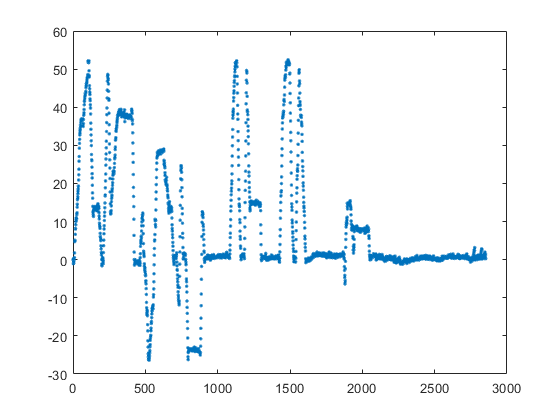


figure(2)
plot(x1,'.')

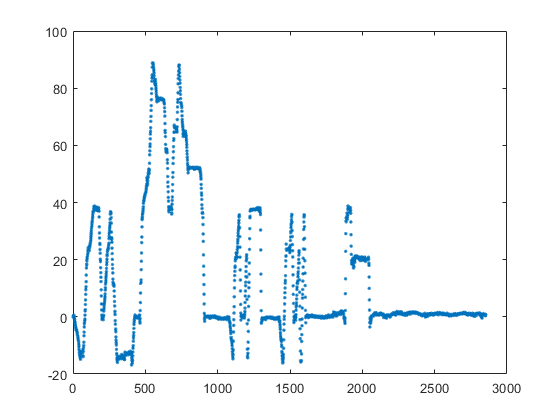

figure(3)
plot(y1,'.')

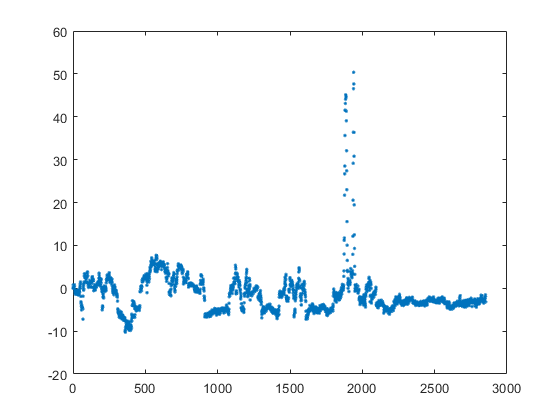

figure(4)
plot(altcm1,'.')

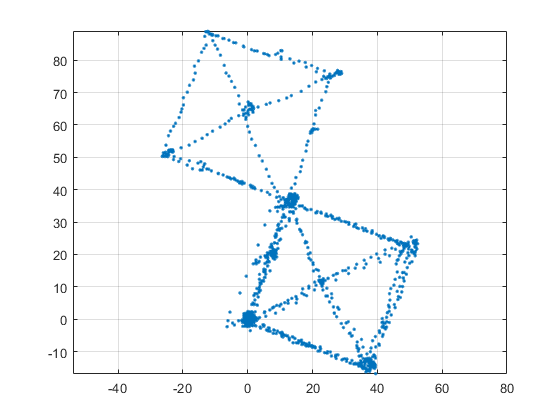


figure(5)
plot(x1,y1,'.')
grid on;
axis equal;

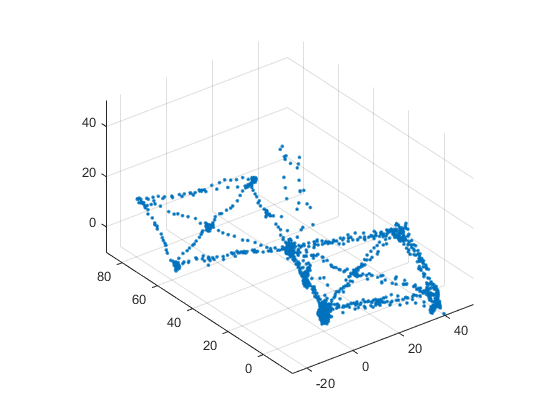


figure(6)
plot3(x1,y1,altcm1,'.')
grid on;
axis equal;

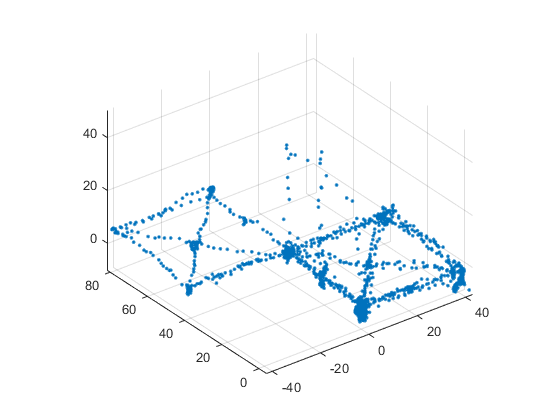


% 設定旋轉角度（以度為單位）
theta_deg = 20;  % 旋轉角度設定為 30 度
theta = deg2rad(theta_deg);  % 轉換為弧度
R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
rotated_coords = R * [x1; y1];
x_r = rotated_coords(1, :);
y_r = rotated_coords(2, :);

figure(7)
plot3(x_r,y_r,altcm1,'.')
grid on;
axis equal;

% 初始化圖形
figure;
h = plot3(NaN, NaN, NaN, '.');  % 初始化一個空的點圖對象

% 設置圖形屬性
axis tight;  % 自動調整軸範圍
xlabel('X');
ylabel('Y');
zlabel('Altitude');
title('3D Animation');

% 循環繪製每一幀
for i = 1:length(x_r)
    % 更新數據
    set(h, 'XData', x_r(1:i), 'YData', y_r(1:i), 'ZData', altcm1(1:i));
    if mod(i, 10) == 0  % 每10幀更新一次
        drawnow;
    end
end

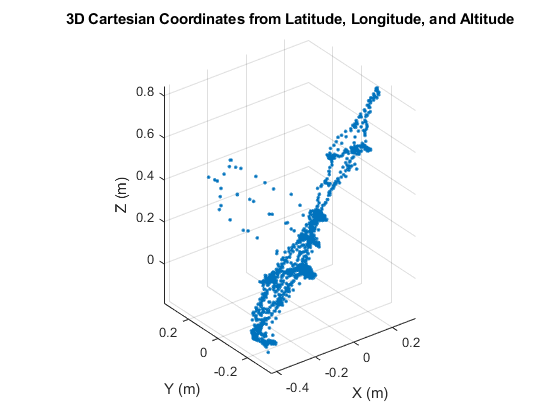


% 地球平均半徑 (公尺)
R = 6371000; 

% 將經緯度轉換為弧度
phi = deg2rad(lat); % 緯度轉弧度
lambda = deg2rad(lon); % 經度轉弧度

% 計算 3D 笛卡爾座標
x3d = (R + alt) .* cos(phi) .* cos(lambda);
y3d = (R + alt) .* cos(phi) .* sin(lambda);
z3d = (R + alt) .* sin(phi);

x3d=x3d-x3d(1);
y3d=y3d-y3d(1);
z3d=z3d-z3d(1);

% 繪製 3D 圖形
figure;
plot3(x3d, y3d, z3d, '.');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('3D Cartesian Coordinates from Latitude, Longitude, and Altitude');
grid on;
axis equal;